ds = "CaseyIslands2017\\";
datapath = ContourLabeler.datapath;
path = datapath + ds;
load(path + "annotations\\annotations.mat")
load(path + "spectrograms\\filterbank.mat")
load(path + "noise\\NoiseEstimate.mat")

ac = AnnotationConverter("D:\\Whale Data\\AcousticTrends_BlueFinLibrary\\BallenyIslands2015\\", "BallenyIslands2015");
ac.convert();

counts = groupcounts(annotationTable, "FileID")

counts = 1128×3 table
    FileID    GroupCount    Percent 
    ______    __________    ________

      29          8          0.23578
      30          5          0.14736
      31          5          0.14736
      32          6          0.17683
      33          6          0.17683
      34          5          0.14736
      35          6          0.17683
      36          4          0.11789
      37          1         0.029472
      38          7          0.20631
      39          4          0.11789
      40          2         0.058945
      41          4          0.11789
      42          1         0.029472
      43          2         0.058945
      44          2         0.058945


fid = 437;
annT = annotationTable(annotationTable.FileID == fid, :)

annT = 6×15 table
                File                 StartIndex     EndIndex     Duration    Annotation    StartFrequency    EndFrequency          OrigFile           FileID    SpectrogramStartIndex    SpectrogramEndIndex    AnnotationToNoiseRatio    AnnotationToNoiseRatioDB    AnnotationSignificance    AnnotationID
    _____________________________    __________    __________    ________    __________    ______________    ____________    _____________________    ______    _____________________    ___________________    ______________________<

filename = annT.File(1)

filename = "2017_02_05_15_08_44_288.wav"

specname = extractBefore(filename, ".wav") + ".mat";
load(path + "spectrograms\\" + specname)
s = s.^2;
figure


c = Contours(fb, s)

c =   Contours with properties:

            hrtol: 0.0400
       NHarmonics: 10
           ratios: [1.1111 1.1250 1.1429 1.1667 1.2000 1.2500 1.2857 1.3333 1.4000 1.4286 1.5000 1.6000 1.6667 1.7500 1.8000 2 2.2500 2.3333 2.5000 2.6667 3 3.3333 3.5000 4 4.5000 5 6 7 8 9 10]
      ratiosTolUp: [1.1556 1.1700 1.1886 1.2133 1.2480 1.3000 1.3371 1.3867 1.4560 1.4857 1.5600 1.6640 1.7333 1.8200 1.8720 2.0800 2.3400 2.4267 2.6000 2.7733 3.1200 3.4667 3.6400 4.1600 4.6800 5.2000 6.2400 7.2800 8.3200 9.3600 10.4000]
    ratiosTolDown: [1.0684 1.0817 1.0989 1.1218 1.1538 1.2019 1.2363 1.2821 1.3462 1.3736 1.4423 1.5385 1.6026 1.6827 1.7308 1.9231 2.1635 2.2436 2.4038 2.5641 2.8846 3.2051 3.3654 3.8462 4.3269 4.8077 5.7692 6.7308 7.6923 8.6538 9.6154]
              tau: 5
             Tmin: 0.5000
           FreqMF: 7
        PHarmonic: 0.8000
        PDuration: 0.9000
      NoiseSmooth: 2
          ProbMul: 1.5000
         BlurStd

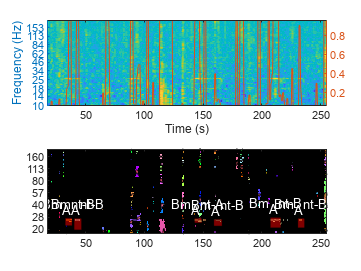

c.Blur = false;
c.fitGMM(true)
c.extractContours()
c.debugplot(fb)
subplot(212)
for i = 1:size(annT, 1)
    row = annT(i, :);
    t = [row.StartIndex, row.EndIndex]/1000;
    fbox = [row.StartFrequency, row.StartFrequency, row.EndFrequency, row.EndFrequency];
    tbox = [t(1), t(2), t(2), t(1)];
    hold on
    fill( tbox, fbox, 'r', "FaceAlpha",0.5, "EdgeAlpha",0.8);
    text(mean(tbox), max(fbox), row.Annotation, "HorizontalAlignment","center", VerticalAlignment="bottom", Color=[1 1 1])
    hold off
end

fid = 2514;
annT = annotationTable(annotationTable.FileID == fid, :)

annT = 3×15 table
                File                 StartIndex     EndIndex     Duration    Annotation    StartFrequency    EndFrequency          OrigFile           FileID    SpectrogramStartIndex    SpectrogramEndIndex    AnnotationToNoiseRatio    AnnotationToNoiseRatioDB    AnnotationSignificance    AnnotationID
    _____________________________    __________    __________    ________    __________    ______________    ____________    _____________________    ______    _____________________    ___________________    ______________________<

filename = annT.File(1)

filename = "2017_10_25_10_30_35_008.wav"

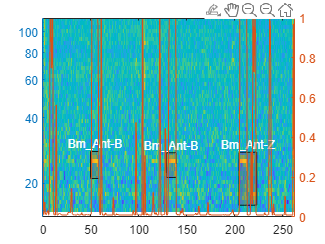

specname = extractBefore(filename, ".wav") + ".mat";
load(path + "spectrograms\\" + specname)
s = s.^2;
fidx = fb.fc >= 10 & fb.fc <= 121;
s = s(fidx, :);

w = noiseEstimates(fidx, fid);
sw = s./w;
% sw = imgaussfilt(sw, [0.1, 30]);
figure

b = BLED();
b.detect(sw);
segmm = SEGMM(3);
segmm.detect(sw);

st = fb.getTime(s);
yyaxis left
Tools.plotTF(sw, fb.fc(fidx), true, true, st)

for i = 1:size(annT, 1)
    row = annT(i, :);
    t = [row.StartIndex, row.EndIndex]/1000;
    fbox = [row.StartFrequency, row.StartFrequency, row.EndFrequency, row.EndFrequency];
    tbox = [t(1), t(2), t(2), t(1)];
    hold on
    fill( tbox, fbox, 'r-', "FaceAlpha",0.2, "EdgeAlpha",0.8);
    text(mean(tbox), max(fbox), row.Annotation, "HorizontalAlignment","center", VerticalAlignment="bottom", Color=[1 1 1], Interpreter="none")
    hold off
end

yyaxis right
plot(st, segmm.probs);